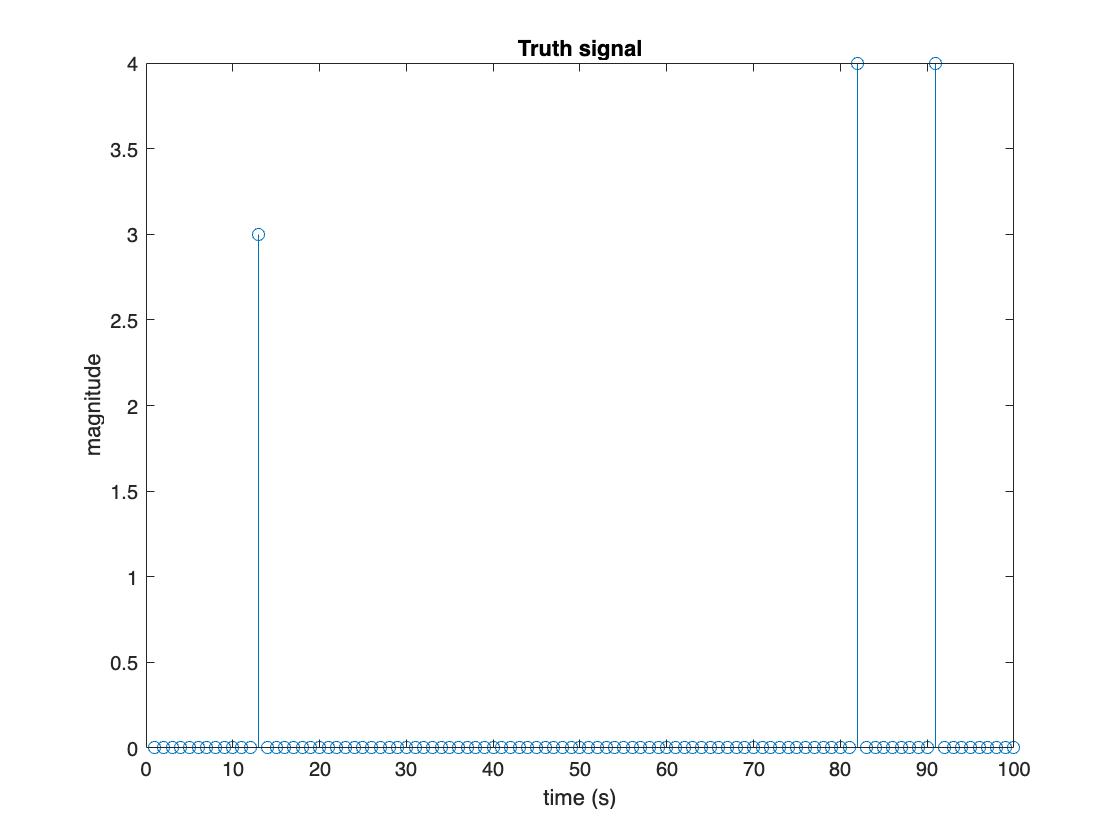

%% compressive sensing

% compressive sensing functions by reconstructing
% signals/images by leveraging a sparsity assumption which
% is true for our simplified point scatterer case. I am
% going to start by reproducing the compressive sensing
% implementation I used for a signal, then I will scale to a
% two-dimensional image

% initialize the length of the signal and the number of
% non-zero points
N = 100; nz = 3; 

% number of measurements and std deviation of error
m = 15; sigma = 0.01;

% formulate a signal with t
truth_signal = zeros(N,1);

% randomly select nz indices to populate with non-zero
% values, randomize the values
nidx = randi(100, nz, 1);
nmag = randi(3:4, nz, 1);
truth_signal(nidx) = nmag;

figure
stem(truth_signal)
title('Truth signal')
xlabel('time (s)')
ylabel('magnitude')


fprintf('Non-zeros indices at: %i, %i and %i', nidx)

Non-zeros indices at: 82, 91 and 13

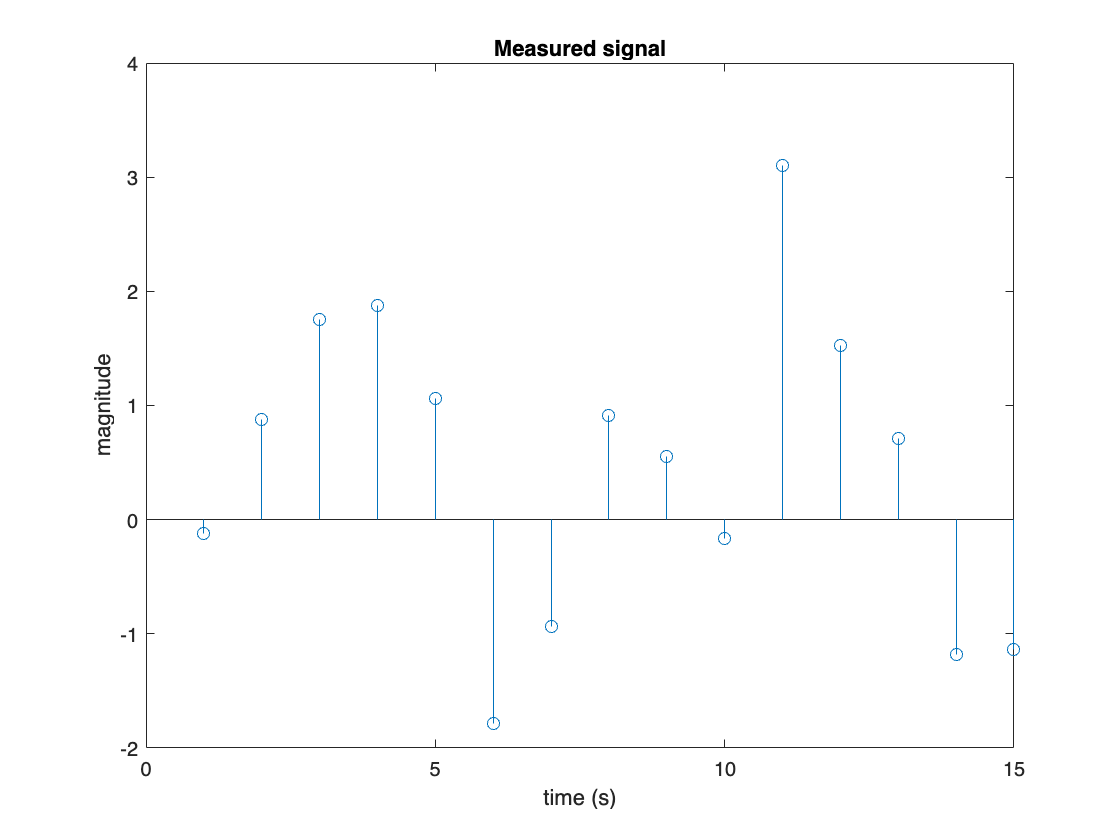

% formulate the measured signal y = Ax + n where A is the
% system or sensing matrix, y is the measurement, x is the
% signal and n is the noise

A = randn(m, N) / sqrt(m);

% calculate the measurement
y = A * truth_signal + sigma * randn(m, 1);

figure
stem(y)
title('Measured signal')
xlabel('time (s)')
ylabel('magnitude')

% Apply compressive sensing techniques using the orthogonal
% matching pursuit method which assumes the columns of A
% (iid Gaussian) are roughly orthogonal. The goal is to
% determine the basis vector in A that is overlaps the most
% with the measurement. This overlap is determined by an
% inner product between the measurement and each vector,
% resulting in the transformation coefficients. The greater
% the magnitude of the coefficient, the greater the overlap.
% Select the basis vector in A with the greatest inner
% product, and solve for an approximation of signal by
% minimizing || y - Ax ||_{2}^{2} using the least squares method 

% initialize the array containing the approximate non-zero
% indices
Lambda = []; x = zeros(N,1);

% for now, assume we have knowledge of the number of
% nonzeros
for i = 1:nz

    % inner product of the measurement and basis vectors
    c = A'*(A'*y - A*x);

    % find the index that maximizes the inner product
    [~, l] = max(abs(c));
    Lambda = [Lambda; l];

    % use this basis vector to calculate the least squares
    % solution
    x(Lambda) = A(:,Lambda)'*inv(A(:,Lambda)'*A(:,Lambda))*y;

end

Arrays have incompatible sizes for this operation.

Related documentation